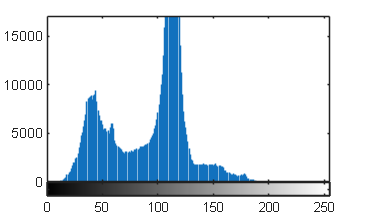

%SE CARGAR LA IMAGEN
I = imread('data/originales/gf2_04.jpg');
%SE PASA LA IMAGEN A ESCALA DE GRISES
Ig = rgb2gray(I);
%se plotea el histograma
figure, imhist(Ig)

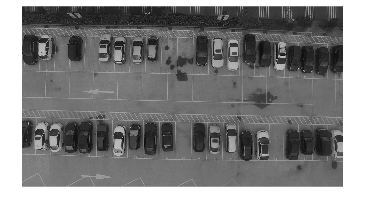

figure, imshow(Ig)

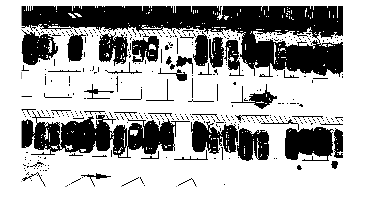

% Umbral
umbralAsfaltoInf = 80;
umbralAsfaltoSup = 130;
% Segmentación del asfalto mediante umbral
mascaraAsfalto = Ig > umbralAsfalto & Ig < umbralAsfaltoSup;
figure, imshow(mascaraAsfalto)

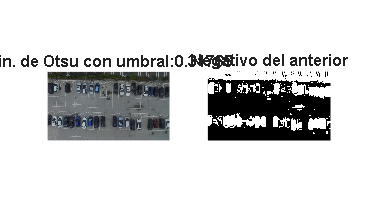

% Umbral 2
% Método de Otsu
level = graythresh(Ig);    % Valor umbral de Otsu
BW2 = imbinarize(Ig,level); % Umbraliza/binariza. Ver manual en web

figure, 
subplot 121, imshow(I), title("Bin. de Otsu con umbral:" + level)
subplot 122, imshow(~BW2), title('Negativo del anterior')

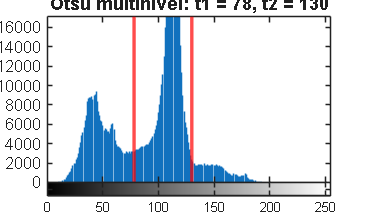

%% 2. Multiumbralización (Otsu con 2 umbrales)
th = multithresh(Ig, 2)   ;                    % ¿dónde caen?
figure, imhist(Ig), hold on
xline(th(1), 'r', 'LineWidth', 2); xline(th(2), 'r', 'LineWidth', 2)
title(sprintf('Otsu multinivel: t1 = %d, t2 = %d', th(1), th(2)))

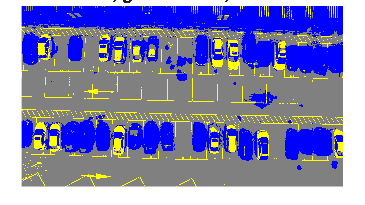


Q = imquantize(Ig, th);                       % 1 = oscuro, 2 = asfalto, 3 = claro
figure, imshow(label2rgb(Q, [0 0 1; 0.5 0.5 0.5; 1 1 0])), title('azul=oscuro, gris=asfalto, amarillo=claro')

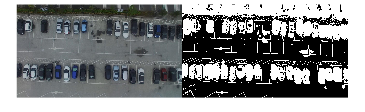


BWauto = (Q == 1) | (Q == 3);                 % candidatos a auto = fuera del asfalto
figure, imshowpair(I, BWauto, 'montage')

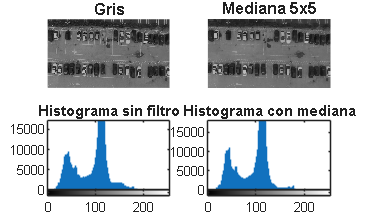

%% 1b. Filtro previo: mediana
Igm = medfilt2(Ig, [5 5]);
figure
subplot 221, imshow(Ig),   title('Gris')
subplot 222, imshow(Igm),  title('Mediana 5x5')
subplot 223, imhist(Ig),   title('Histograma sin filtro')
subplot 224, imhist(Igm),  title('Histograma con mediana')


%% 2'. Multiumbralización sobre la imagen filtrada
th_f = multithresh(Igm, 2)

th_f = 1×2 uint8 row vector
    79   130


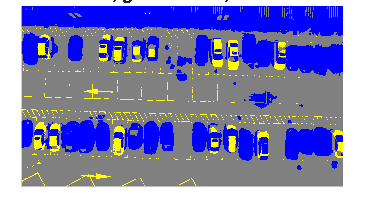

%th_f(2) = th_f(2)-10;
Qf   = imquantize(Igm, th_f);
figure, imshow(label2rgb(Qf, [0 0 1; 0.5 0.5 0.5; 1 1 0])), title('azul=oscuro, gris=asfalto, amarillo=claro')

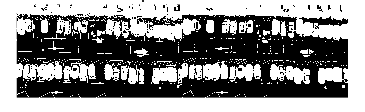

BWf  = (Qf == 1) | (Qf == 3);
figure, imshowpair(BWauto, BWf, 'montage'), title('Sin filtro  |  Con mediana 5x5')

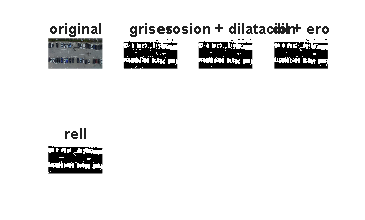

Disco      Precision=0.584  Recall=0.827  IoU=0.521
Cuadrado   Precision=0.601  Recall=0.829  IoU=0.535


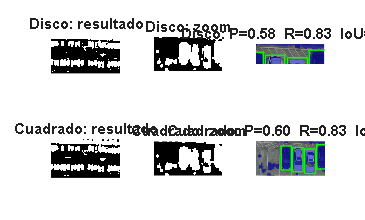

%funciones de morlogia para eliminar lineas y puntos(ruido)
BW = BWf;
r1 = 2;
figure
imorf1 = imopen(BW, strel('disk', r1));
subplot 243, imshow(imorf1), title("erosion + dilatacion")
subplot 241, imshow(I), title('original')
subplot 242, imshow(BW), title('grises')

r2 = 3;

imorf2 = imclose(imorf1, strel('disk', r2));
subplot 244, imshow(imorf2), title("dil + ero")

imorf3 = imfill(imorf2, 'holes');     % une partes cercanas
subplot 245, imshow(imorf3), title("rell")